# Modelling - Decision Tree & K-Nearest Neighbor

## 0) Setup

Clear workspace, load datasets with different preprocessings and convert to matrices

clear; clc; % Clear workspace
rng(1) % set seed for reproducability

% Load baseline train and test data
train = readtable('train.csv', 'ReadVariableNames', true);
test = readtable('test.csv', 'ReadVariableNames', true);

feature_names = train.Properties.VariableNames(2:end);

train = train{:,:};  % Convert to matrix
test = test{:,:};

X_train = train(:, 2:end); % Split into target and features 
y_train = train(:, 1);
X_test = test(:, 2:end);
y_test = test(:, 1);

% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

## 1) Train / Test Baseline Models with Default Parameters

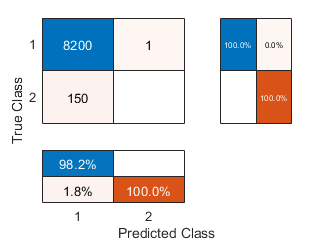

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

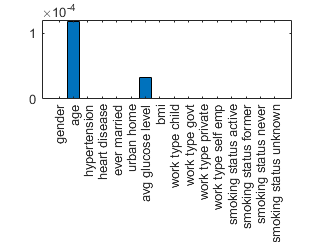

% Show feature importance
imp = predictorImportance(dt_base);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

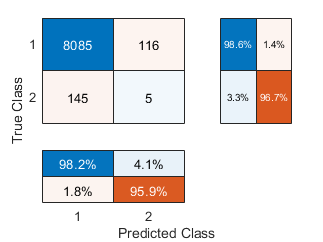

accuracy = 0.9687

precision = 0.0413

recall = 0.0333

specificity = 0.9859

fb = 0.0347

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Standardize', 1, 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

## 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy)

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 10);

% DECISION TREE: Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
ParamsDT = [MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
n = optimizableVariable('n',[1,16],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
ParamsKNN = [n; dst];

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014878 |     0.43786 |    0.014878 |    0.014878 |           22 |            3 |
|    2 | Best   |    0.014759 |     0.29124 |    0.014759 |    0.014759 |            3 |           30 |
|    3 | Accept |    0.014819 |     0.34849 |    0.014759 |    0.014759 |            6 |            2 |
|    4 | Accept |    0.014759 |     0.49523 |    0.014759 |    0.014759 |           12 |           29 |
|    5 | Accept |    0.014819 |     0.46992 |    0.014759 |    0.014759 |           29 |           14 |
|    6 | Accept |    0.014759 |      0.4218 |    0.014759 |    0

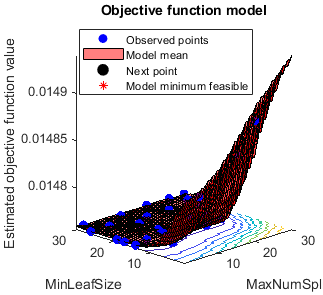

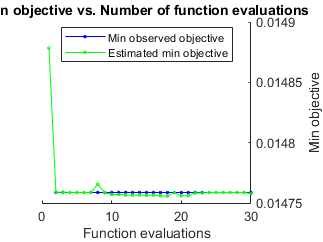


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 33.3144 seconds
Total objective function evaluation time: 13.5633

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         3             30     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.29124

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        21             15     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.50292



% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

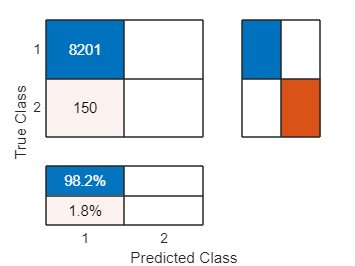

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

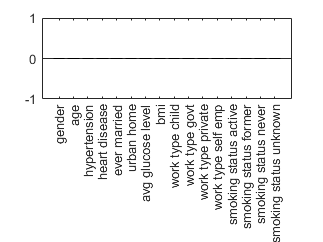

% Show feature importance
imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014908 |      6.2616 |    0.014908 |    0.014908 |            6 |    euclidean |
|    2 | Best   |    0.014759 |      5.7405 |    0.014759 |    0.014833 |           10 |       cosine |
|    3 | Accept |    0.014759 |      5.4498 |    0.014759 |    0.014759 |           15 |    euclidean |
|    4 | Accept |    0.025626 |      4.8241 |    0.014759 |    0.014974 |            2 |       cosine |
|    5 | Accept |    0.014759 |      5.1367 |    0.014759 |    0.014759 |           12 |    euclidean |
|    6 | Accept |    0.014759 |       5.873 |    0.014759 |    0

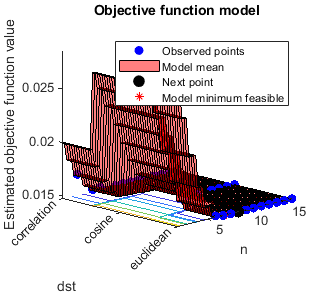

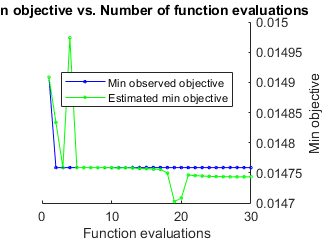


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 197.3327 seconds
Total objective function evaluation time: 174.7165

Best observed feasible point:
    n      dst  
    __    ______

    10    cosine

Observed objective function value = 0.014759
Estimated objective function value = 0.014762
Function evaluation time = 5.7405

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    7    euclidean

Estimated objective function value = 0.014743
Estimated function evaluation time = 5.7019



% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

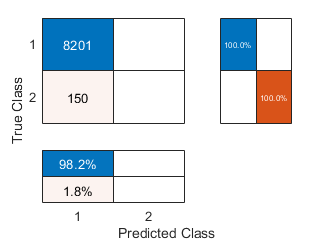

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.26971 |           1 |           1 |            2 |           23 |
|    2 | Accept |           1 |     0.41122 |           1 |           1 |           28 |           11 |
|    3 | Accept |           1 |     0.31728 |           1 |           1 |            7 |           21 |
|    4 | Best   |     0.99747 |     0.41105 |     0.99747 |     0.99747 |           21 |            3 |
|    5 | Accept |           1 |     0.52797 |     0.99747 |     0.99747 |           25 |           24 |
|    6 | Best   |     0.99747 |     0.45459 |     0.99747 |     

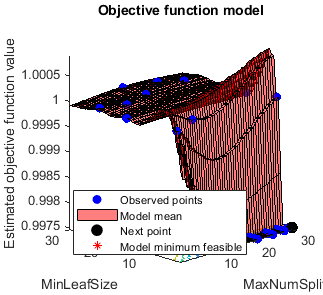

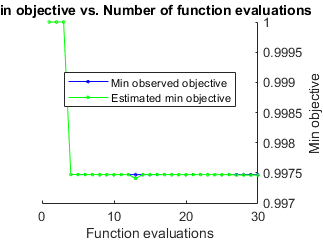


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 31.0824 seconds
Total objective function evaluation time: 13.1023

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        13              3     

Observed objective function value = 0.99747
Estimated objective function value = 0.99748
Function evaluation time = 0.45459

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        15              3     

Estimated objective function value = 0.99746
Estimated function evaluation time = 0.44383



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

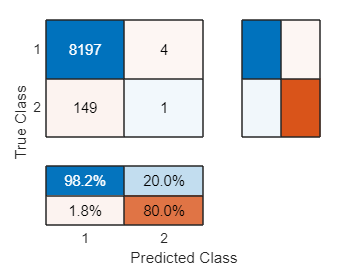

accuracy = 0.9817

precision = 0.2000

recall = 0.0067

specificity = 0.9995

fb = 0.0083


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

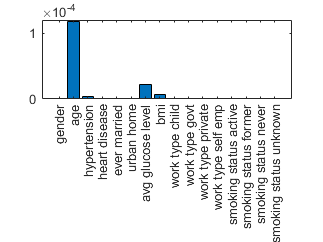

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.96968 |      5.1662 |     0.96968 |     0.96968 |            1 |       cosine |
|    2 | Accept |           1 |      5.1719 |     0.96968 |     0.97125 |           15 |       cosine |
|    3 | Accept |     0.99752 |      5.3769 |     0.96968 |     0.98041 |            4 |       cosine |
|    4 | Accept |           1 |      6.5392 |     0.96968 |     0.98013 |           11 |    euclidean |
|    5 | Accept |           1 |       5.787 |     0.96968 |     0.97152 |           14 |  correlation |
|    6 | Accept |           1 |      5.7686 |     0.96968 |     

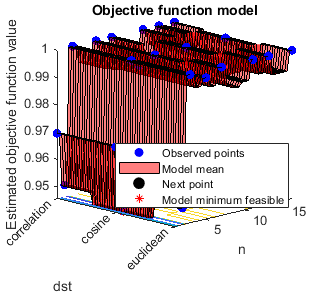

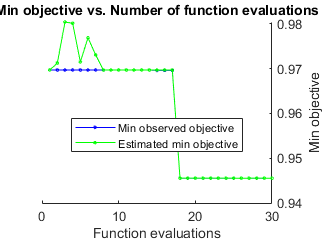


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 216.4291 seconds
Total objective function evaluation time: 192.6734

Best observed feasible point:
    n     dst  
    _    ______

    2    cosine

Observed objective function value = 0.94554
Estimated objective function value = 0.94554
Function evaluation time = 7.6966

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    2    cosine

Estimated objective function value = 0.94554
Estimated function evaluation time = 6.2691



% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 4) Hyperparameter Tuning Models (CV = stratify, loss = accuracy)

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 10, 'Stratify', true);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014789 |      0.4396 |    0.014789 |    0.014789 |            6 |            2 |
|    2 | Best   |    0.014759 |     0.44542 |    0.014759 |     0.01476 |            8 |           18 |
|    3 | Accept |    0.014759 |     0.63409 |    0.014759 |    0.014759 |           22 |           23 |
|    4 | Accept |    0.014759 |     0.51122 |    0.014759 |    0.014758 |           14 |           19 |
|    5 | Accept |    0.014759 |      0.5668 |    0.014759 |    0.014759 |           17 |           27 |
|    6 | Accept |    0.014849 |     0.49992 |    0.014759 |    0

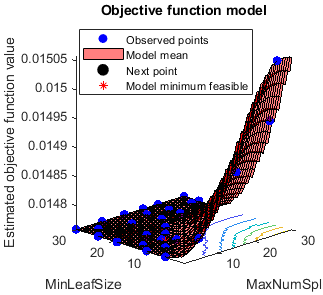

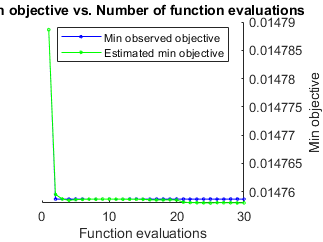


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 38.661 seconds
Total objective function evaluation time: 14.6653

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         8             18     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.44542

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         8             14     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.46491



% 4a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 4a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c_strat, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014759 |      11.554 |    0.014759 |    0.014759 |           15 |  correlation |
|    2 | Accept |    0.014759 |      10.097 |    0.014759 |    0.014759 |           12 |    euclidean |
|    3 | Accept |    0.014759 |      7.1378 |    0.014759 |    0.014759 |           13 |       cosine |
|    4 | Accept |    0.023291 |      5.9455 |    0.014759 |     0.01476 |            2 |       cosine |
|    5 | Accept |    0.014759 |      5.7879 |    0.014759 |    0.014759 |           14 |    euclidean |
|    6 | Accept |    0.014998 |      5.7513 |    0.014759 |    0

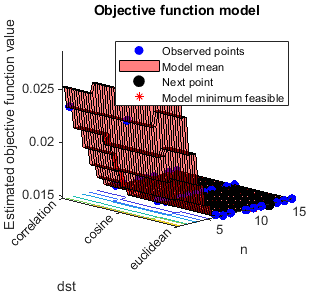

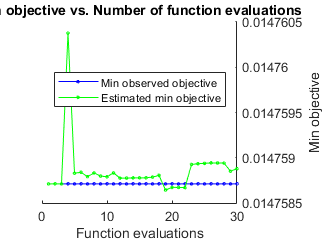


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 205.3339 seconds
Total objective function evaluation time: 182.7454

Best observed feasible point:
    n         dst    
    __    ___________

    15    correlation

Observed objective function value = 0.014759
Estimated objective function value = 0.014758
Function evaluation time = 11.5541

Best estimated feasible point (according to models):
    n      dst  
    __    ______

    13    cosine

Estimated objective function value = 0.014759
Estimated function evaluation time = 5.9569



% 4b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 4b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c_strat, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 5) Hyperparameter Tuning Models (CV = statify, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.51237 |           1 |           1 |           30 |           23 |
|    2 | Accept |           1 |     0.47073 |           1 |           1 |            2 |            8 |
|    3 | Best   |     0.99495 |     0.85358 |     0.99495 |     0.99827 |           29 |            9 |
|    4 | Accept |           1 |     0.84111 |     0.99495 |     0.99871 |           18 |           30 |
|    5 | Accept |           1 |     0.47802 |     0.99495 |     0.99899 |           24 |            3 |
|    6 | Accept |           1 |     0.82481 |     0.99495 |     

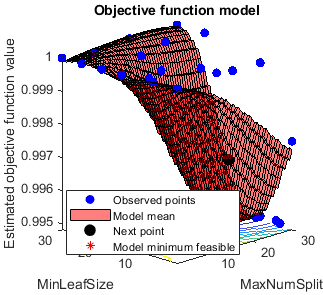

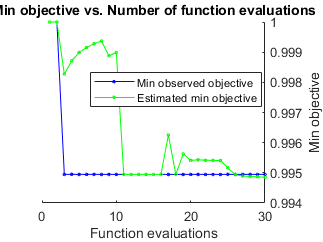


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 47.3854 seconds
Total objective function evaluation time: 17.8391

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              9     

Observed objective function value = 0.99495
Estimated objective function value = 0.99502
Function evaluation time = 0.85358

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26             11     

Estimated objective function value = 0.99485
Estimated function evaluation time = 0.46709



% 5a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 5a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.98765 |      6.1508 |     0.98765 |     0.98765 |            3 |       cosine |
|    2 | Best   |     0.95766 |      19.071 |     0.95766 |     0.97265 |            1 |  correlation |
|    3 | Accept |           1 |      14.554 |     0.95766 |     0.98163 |           13 |    euclidean |
|    4 | Accept |           1 |       8.981 |     0.95766 |      0.9597 |           15 |  correlation |
|    5 | Accept |           1 |      5.3659 |     0.95766 |     0.95767 |            9 |  correlation |
|    6 | Accept |           1 |      5.6304 |     0.95766 |     

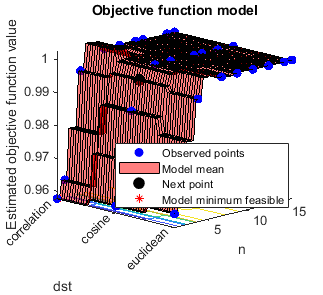

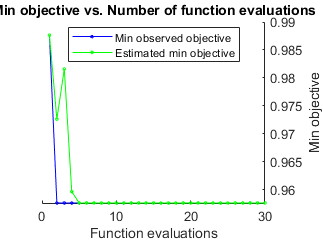


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 220.4363 seconds
Total objective function evaluation time: 195.2503

Best observed feasible point:
    n        dst    
    _    ___________

    1    correlation

Observed objective function value = 0.95766
Estimated objective function value = 0.95766
Function evaluation time = 19.0713

Best estimated feasible point (according to models):
    n        dst    
    _    ___________

    1    correlation

Estimated objective function value = 0.95766
Estimated function evaluation time = 6.1454



% 5b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat); % see helper function

% 5b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

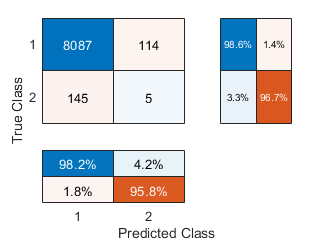

accuracy = 0.9690

precision = 0.0420

recall = 0.0333

specificity = 0.9861

fb = 0.0348


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE)

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 10);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.089377 |      1.3095 |    0.089377 |    0.089377 |           23 |           13 |
|    2 | Accept |     0.13853 |     0.62437 |    0.089377 |    0.092105 |            2 |           28 |
|    3 | Accept |     0.11665 |     0.82533 |    0.089377 |     0.08938 |           10 |           30 |
|    4 | Best   |    0.089286 |       1.068 |    0.089286 |    0.089282 |           29 |           27 |
|    5 | Accept |     0.10799 |      0.7638 |    0.089286 |    0.089279 |           13 |           24 |
|    6 | Accept |     0.10799 |     0.75975 |    0.089286 |     

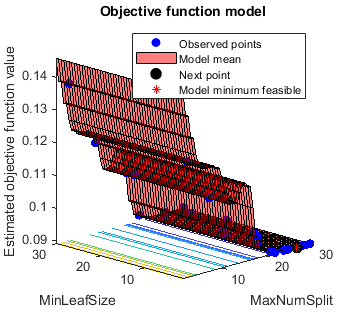

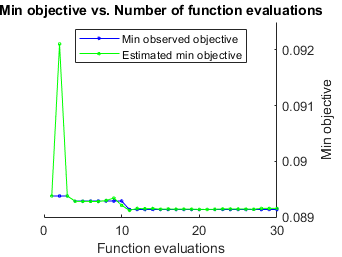


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 55.301 seconds
Total objective function evaluation time: 26.7888

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        27              1     

Observed objective function value = 0.089134
Estimated objective function value = 0.089148
Function evaluation time = 1.1172

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              1     

Estimated objective function value = 0.089154
Estimated function evaluation time = 0.94361



% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

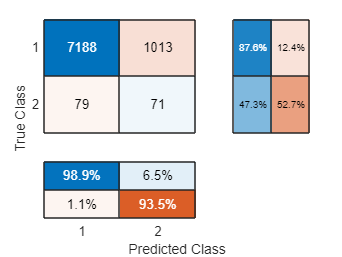

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.2108

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

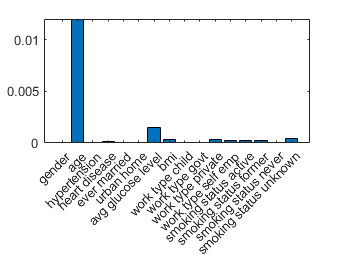

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.018535 |      24.907 |    0.018535 |    0.018535 |           14 |  correlation |
|    2 | Best   |    0.013506 |      38.689 |    0.013506 |     0.01457 |            6 |  correlation |
|    3 | Accept |     0.01896 |      24.961 |    0.013506 |    0.013507 |           15 |       cosine |
|    4 | Accept |    0.016074 |      26.771 |    0.013506 |    0.013513 |           10 |       cosine |
|    5 | Accept |    0.016909 |      31.808 |    0.013506 |    0.013509 |           11 |    euclidean |
|    6 | Best   |      0.0134 |      26.017 |      0.0134 |    0

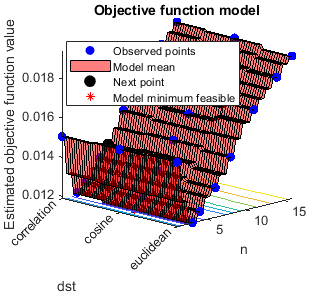

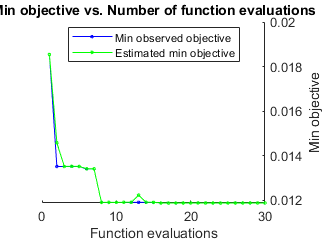


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 853.2443 seconds
Total objective function evaluation time: 823.82

Best observed feasible point:
    n     dst  
    _    ______

    3    cosine

Observed objective function value = 0.011865
Estimated objective function value = 0.011866
Function evaluation time = 22.6424

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    3    cosine

Estimated objective function value = 0.011866
Estimated function evaluation time = 27.0872



% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

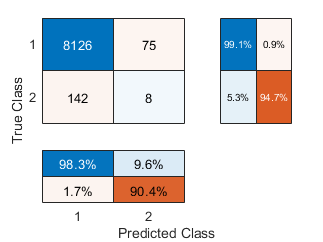

accuracy = 0.9740

precision = 0.0964

recall = 0.0533

specificity = 0.9909

fb = 0.0586

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 7) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.090343 |     0.52353 |    0.090343 |    0.090343 |            2 |           23 |
|    2 | Best   |    0.065228 |      0.9211 |    0.065228 |    0.066479 |           28 |           11 |
|    3 | Accept |    0.087802 |     0.70575 |    0.065228 |    0.065231 |            7 |           21 |
|    4 | Accept |    0.068324 |     0.91469 |    0.065228 |    0.065228 |           21 |            3 |
|    5 | Accept |    0.065271 |     0.97907 |    0.065228 |    0.065219 |           25 |           24 |
|    6 | Accept |    0.073885 |     0.77913 |    0.065228 |    0

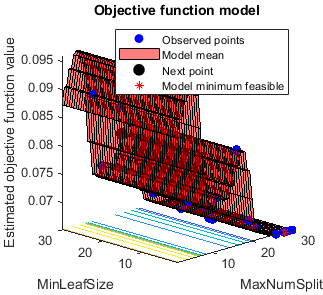

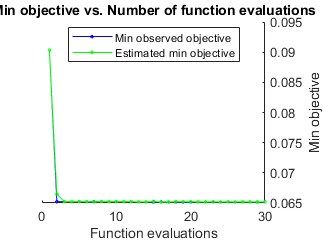


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 48.6722 seconds
Total objective function evaluation time: 27.2964

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.06518
Estimated objective function value = 0.065231
Function evaluation time = 1.0049

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        28              1     

Estimated objective function value = 0.065188
Estimated function evaluation time = 0.94407



% 7a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 7a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 7a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

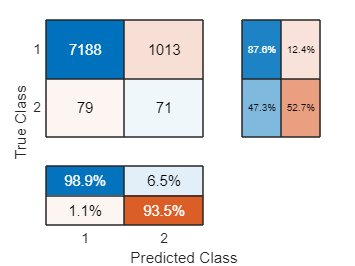

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.2108


% 7a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 7a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

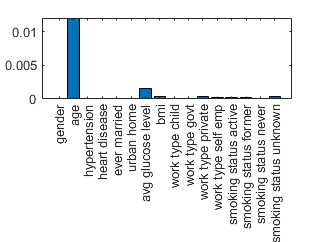

imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.013691 |      21.101 |    0.013691 |    0.013691 |            1 |       cosine |
|    2 | Accept |    0.014854 |      30.914 |    0.013691 |    0.014216 |           15 |       cosine |
|    3 | Best   |    0.012716 |      30.019 |    0.012716 |    0.012717 |            4 |       cosine |
|    4 | Accept |    0.014268 |      22.025 |    0.012716 |    0.012717 |           11 |    euclidean |
|    5 | Accept |    0.014742 |      24.317 |    0.012716 |    0.012717 |           14 |  correlation |
|    6 | Accept |    0.013344 |      33.748 |    0.012716 |    0

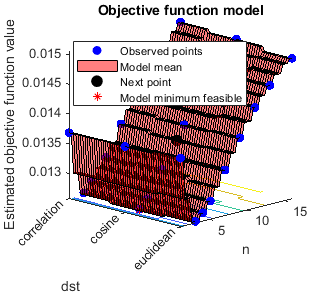

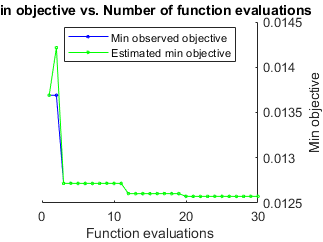


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 883.7276 seconds
Total objective function evaluation time: 833.134

Best observed feasible point:
    n     dst  
    _    ______

    3    cosine

Observed objective function value = 0.012573
Estimated objective function value = 0.012573
Function evaluation time = 24.5862

Best estimated feasible point (according to models):
    n     dst  
    _    ______

    3    cosine

Estimated objective function value = 0.012573
Estimated function evaluation time = 27.3867



% 7b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 7b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 7b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9740

precision = 0.0964

recall = 0.0533

specificity = 0.9909

fb = 0.0586


% 7b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst));

% 7b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) % Metrics
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);

        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', cv_part, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 2; % beta < 1 favors precision. beta > 1 favors recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2*fn + fp); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 